# Lab 5 – Fast Fourier Transform

## 5.2.1 Shifting the Frequency Range

##  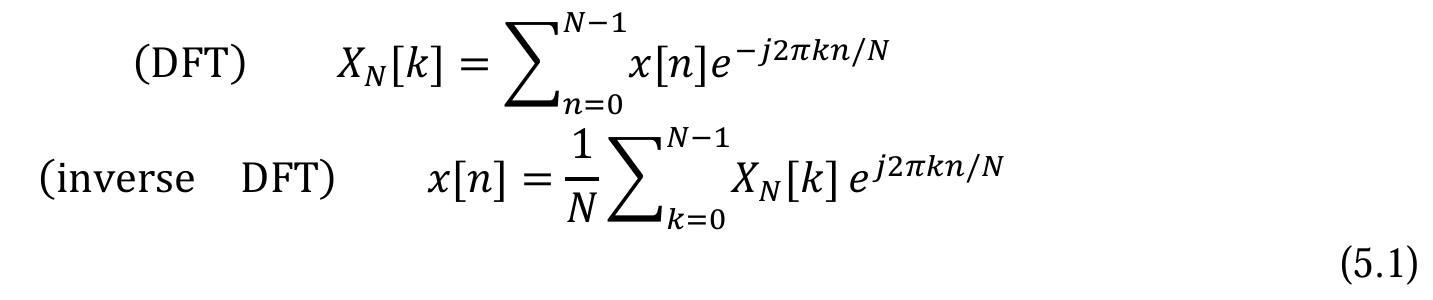

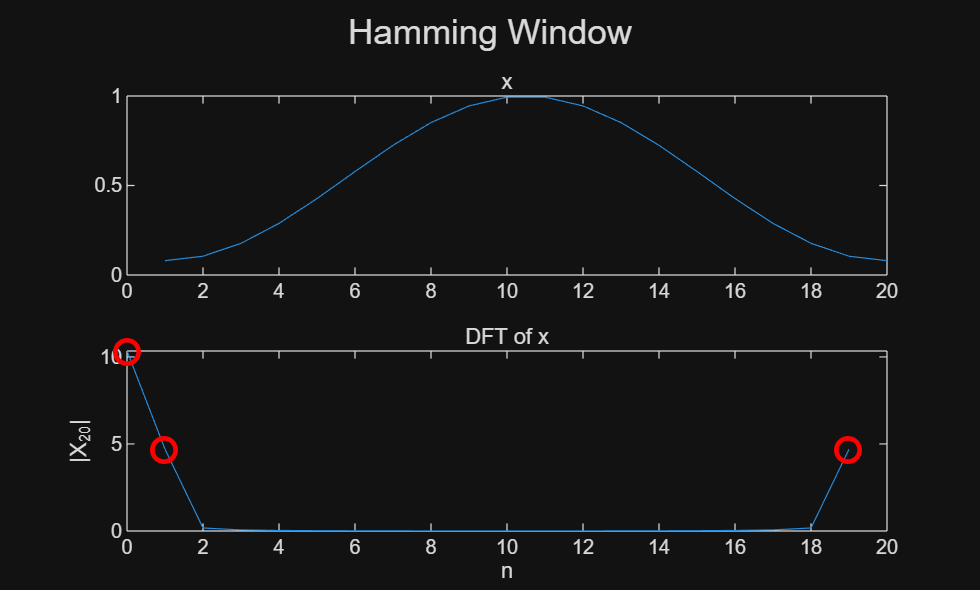

x = hamming(20);
subplot(211)
plot(x), title("x")
X = DFTsum(x);
subplot(212)
sgtitle("Hamming Window")
k = 0:19;
plot(k, abs(X)), ylabel("x")
hold on
plot(0, abs(X(1)), 'ro', 'MarkerSize', 10, 'LineWidth', 2)
plot(1, abs(X(2)), 'ro', 'MarkerSize', 10, 'LineWidth', 2)
plot(19, abs(X(end)), 'ro', 'MarkerSize', 10, 'LineWidth', 2)
title("DFT of x"), xlabel("n"), ylabel("|X_{20}|")
hold off

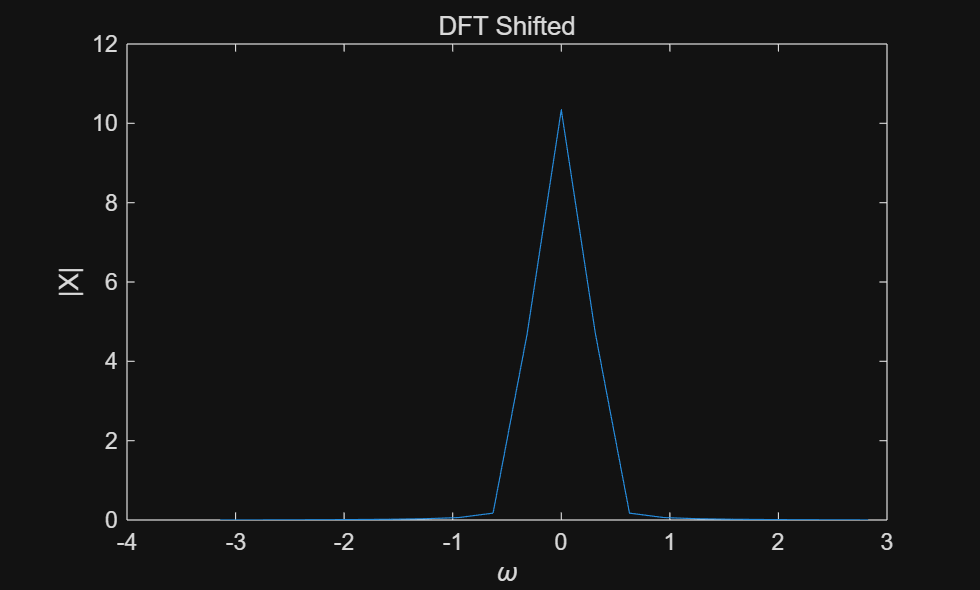

figure
w = 2*pi*k/20;
w(w>=pi) = w(w>=pi) - 2*pi;
plot(fftshift(w), fftshift(abs(X)))
xlabel("\omega"), ylabel("|X|"), title("DFT Shifted")

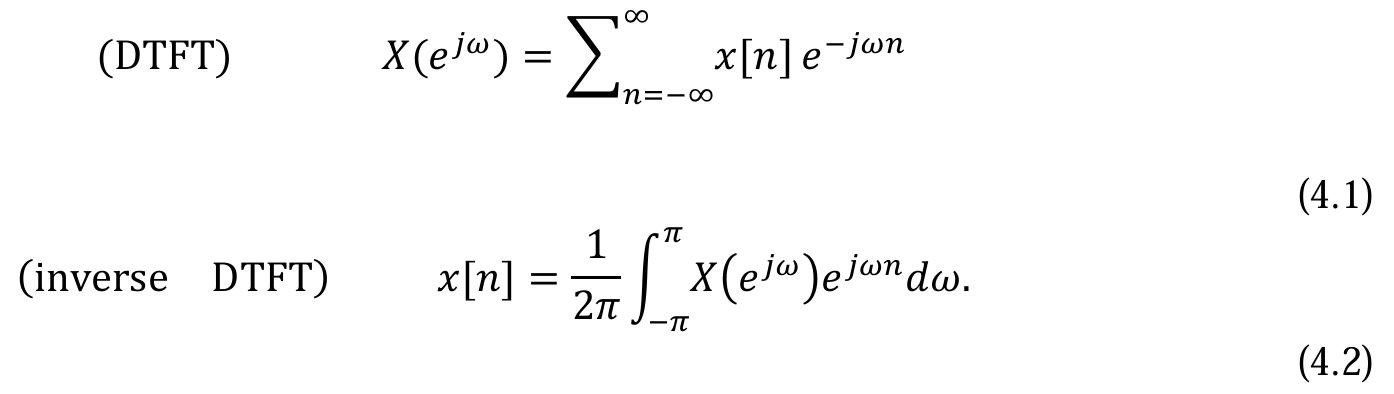

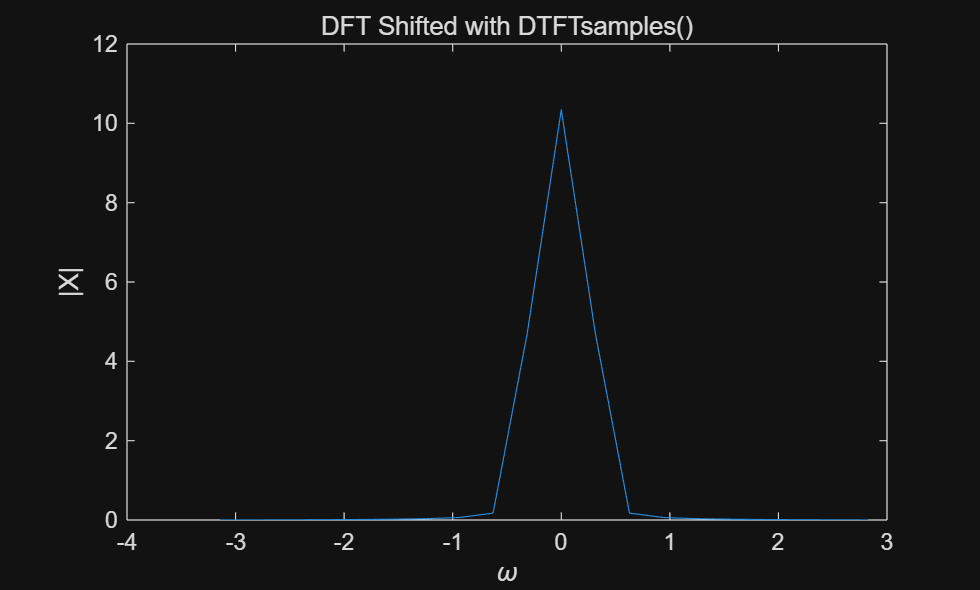

[X_s, w_s] = DTFTsamples(x);
figure
plot(w_s, abs(X_s))
xlabel("\omega"), ylabel("|X|"), title("DFT Shifted with DTFTsamples()")

## 5.2.2 Zero Padding

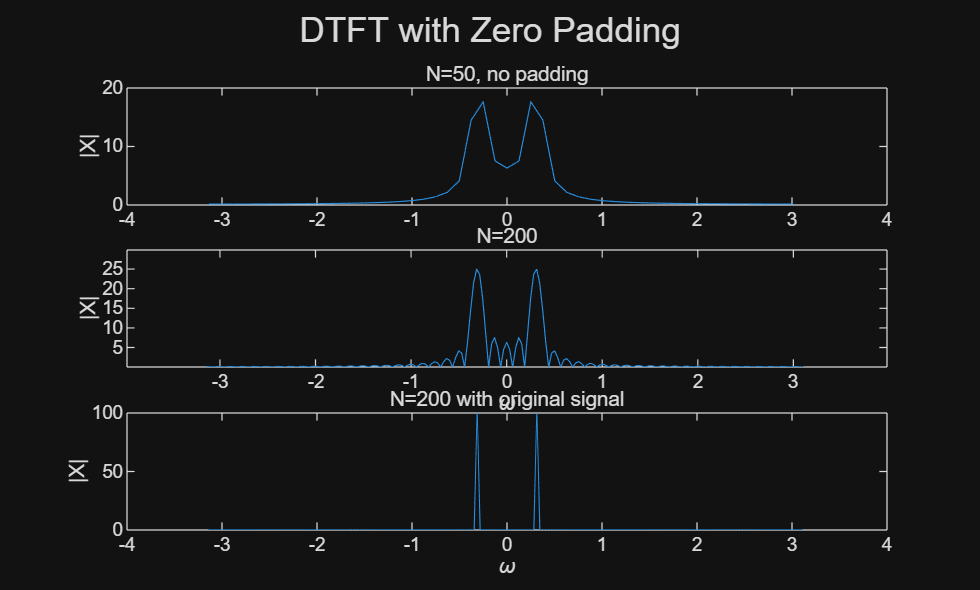

figure,clear

x1=sin(0.1*pi.*(0:49));
x2=[x1, zeros(1,150)];
[X1, w1] = DTFTsamples(x1);
[X2, w2] = DTFTsamples(x2);

subplot(311)
plot(w1, abs(X1))
title("N=50, no padding"), ylabel("|X|")
sgtitle("DTFT with Zero Padding")

subplot(312)
plot(w2, abs(X2))
title("N=200"), ylabel("|X|"), xlabel("\omega")
subplot(313)
x3 = sin(0.1*pi.*(0:199));
[X3, w3] = DTFTsamples(x3);
plot(w3, abs(X3))
title("N=200 with original signal"), ylabel("|X|"), xlabel("\omega")

Obviously, the one with paddings looks more like the true DTFT.

First, DTFT point precision is determined by the number of signal samples. Padding adds points, therefore allowing higher precision.

Next, padding is the same with multiplying a rectangle window to the original signal, therefore the typical ripples are seen.

## 5.3.1 Implementation of Divide-and-Conquer DFT

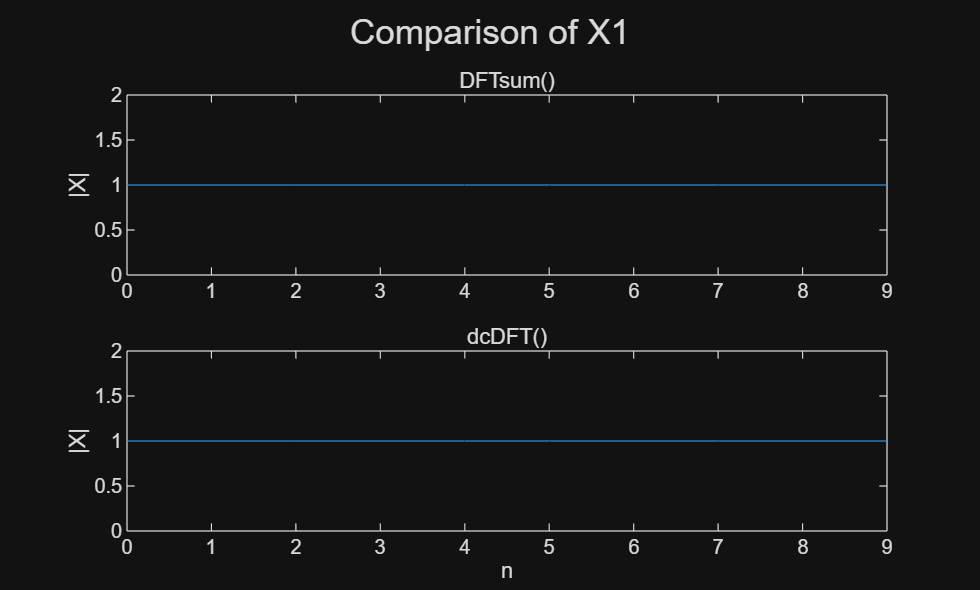

clear

n = 0:9;
x1 = [1, zeros(1, 9)];
x2 = ones(1, 10);
x3 = exp(1j*2*pi*n/10);

figure, subplot(211), sgtitle('Comparison of X1')
plot(n, abs(DFTsum(x1)))
title('DFTsum()'), ylabel('|X|')
subplot(212)
plot(n, abs(dcDFT(x1)))
title('dcDFT()'), ylabel('|X|'), xlabel('n')

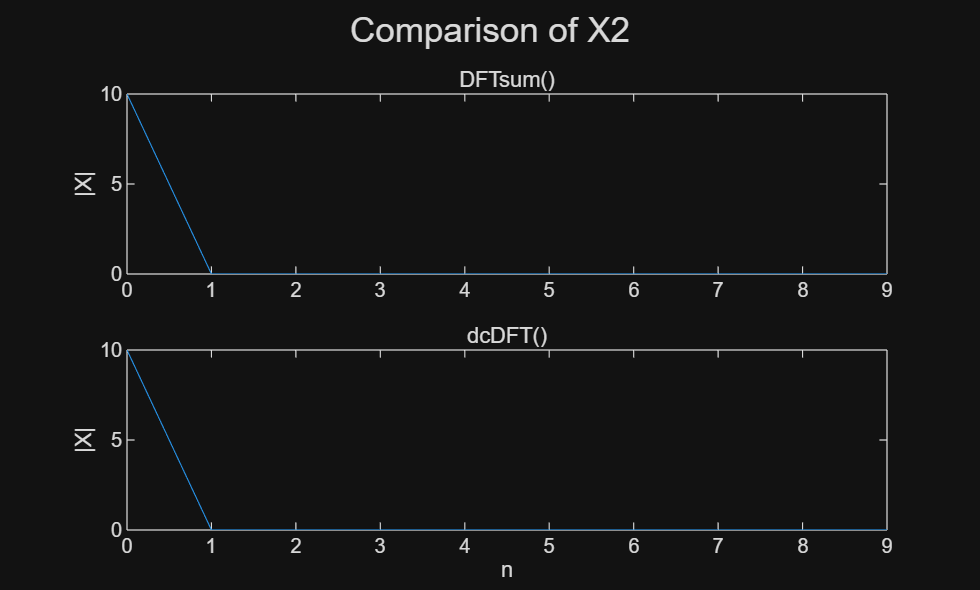

figure, subplot(211), sgtitle('Comparison of X2')
plot(n, abs(DFTsum(x2)))
title('DFTsum()'), ylabel('|X|')
subplot(212)
plot(n, abs(dcDFT(x2)))
title('dcDFT()'), ylabel('|X|'), xlabel('n')

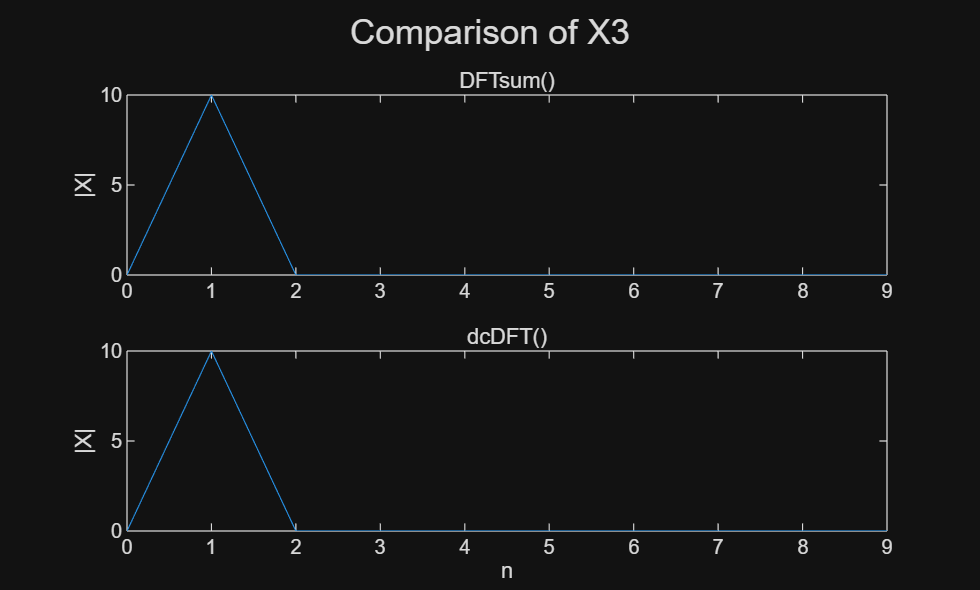

figure, subplot(211), sgtitle('Comparison of X3')
plot(n, abs(DFTsum(x3)))
title('DFTsum()'), ylabel('|X|')
subplot(212)
plot(n, abs(dcDFT(x3)))
title('dcDFT()'), ylabel('|X|'), xlabel('n')

Required number of multiplication: ${\left(\frac{N}{2}\right)}^2 \times 2+N=\frac{N^2 }{2}+N$

## 5.3.2 Recursive Divide and Conquer

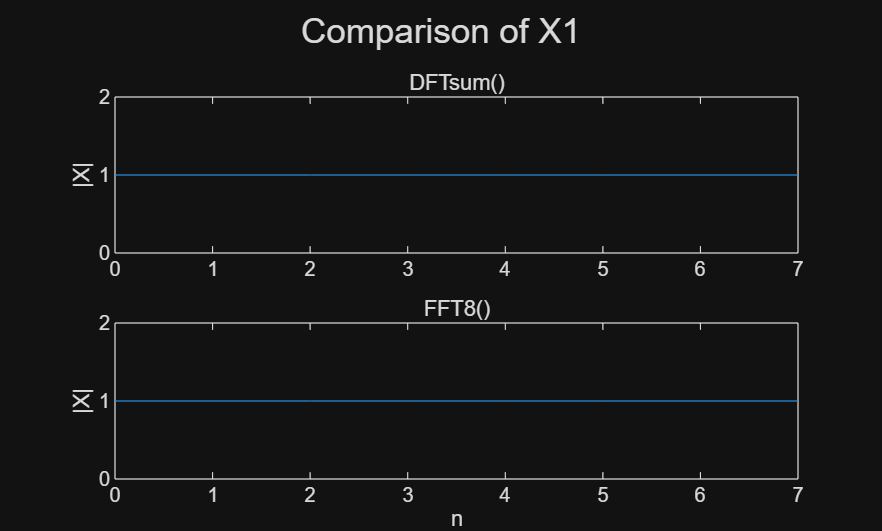

clear
n=0:7;
x1 = [1, zeros(1, 7)];
x2 = ones(1, 8);
x3 = exp(1j*2*pi*n/8);

figure, subplot(211), sgtitle('Comparison of X1')
plot(n, abs(DFTsum(x1)))
title('DFTsum()'), ylabel('|X|')
subplot(212)
plot(n, abs(FFT8(x1)))
title('FFT8()'), ylabel('|X|'), xlabel('n')

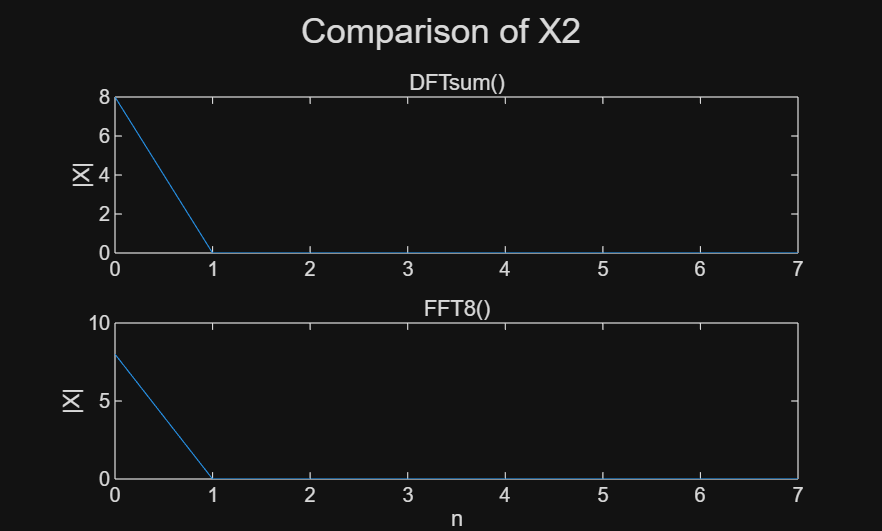

figure, subplot(211), sgtitle('Comparison of X2')
plot(n, abs(DFTsum(x2)))
title('DFTsum()'), ylabel('|X|')
subplot(212)
plot(n, abs(FFT8(x2)))
title('FFT8()'), ylabel('|X|'), xlabel('n')

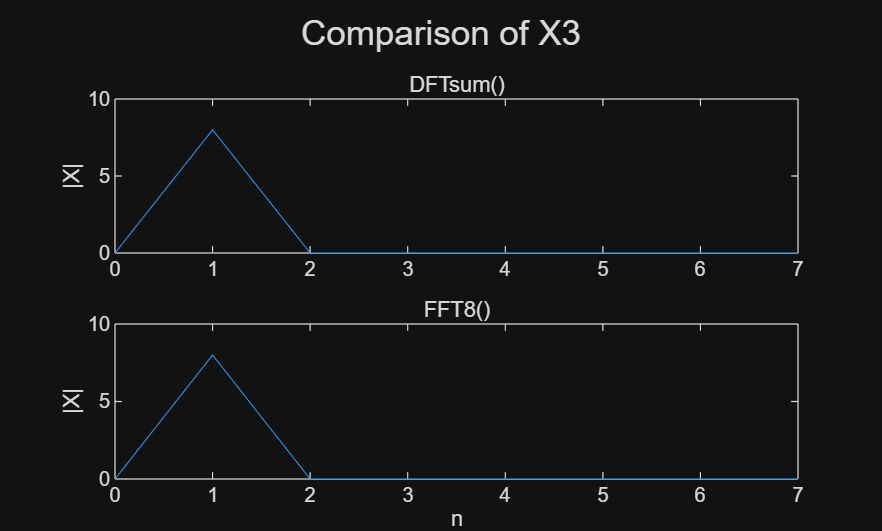

figure, subplot(211), sgtitle('Comparison of X3')
plot(n, abs(DFTsum(x3)))
title('DFTsum()'), ylabel('|X|')
subplot(212)
plot(n, abs(FFT8(x3)))
title('FFT8()'), ylabel('|X|'), xlabel('n')

Required number of multiplication:


$$N+2\times \left(\frac{N}{2}+2\times \left(\frac{N}{4}\right)\right)=N+N+N=3N=12$$


In general:


$$\begin{array}{l}
N=2^p \\
\mathrm{#Multiplication}=N+2\times \left(\frac{N}{2}+2\times \left(\frac{N}{4}+2\times \left(\cdots \right)\right)\right)=N\cdot p=N\;\log_2 N
\end{array}$$



$$p=10:$$



$$\mathrm{#Mulplications}\;\mathrm{in}\;\mathrm{DFTsum}=2^{20}$$



$$\mathrm{#Mulplications}\;\mathrm{in}\;\mathrm{FFT}=2^{11}$$
